# Puma 560: Assembling and Plotting functions

## Getting Links information (V&F)

clear
[L0 L1 L2 L3 L4 L5 L6]=Get_Link_V_F;

## The model

mdl_puma560
p560

 
p560 = 
 
Puma 560 [Unimation]:: 6 axis, RRRRRR, stdDH, fastRNE            
 - viscous friction; params of 8/95;                             
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|          0|     1.5708|          0|
|  2|         q2|          0|     0.4318|          0|          0|
|  3|         q3|    0.15005|     0.0203|    -1.5708|          0|
|  4|         q4|     0.4318|          0|     1.5708|          0|
|  5|         q5|          0|          0|    -1.5708|          0|
|  6|         q6|          0|          0|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


Loading STL models from ARTE Robotics Toolbox for Education  by Arturo Gil (http://arvc.umh.es/arte).......


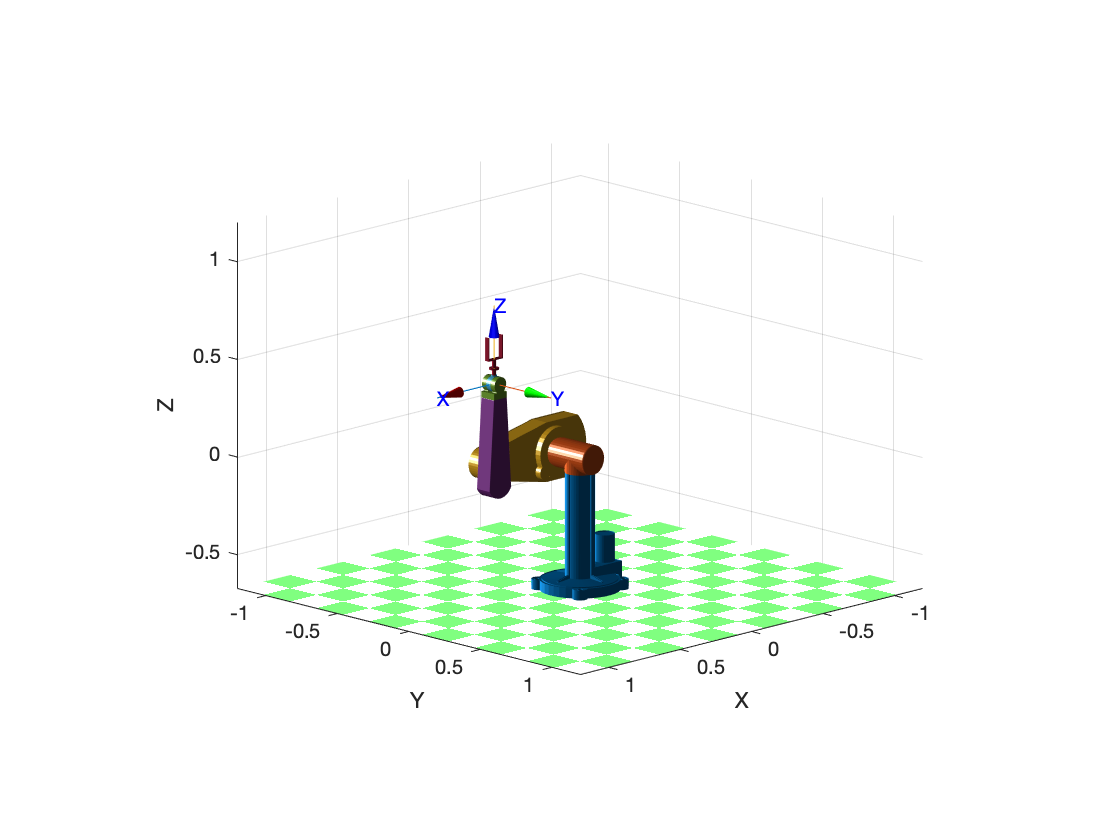

p560.plot3d(qz)

## Transform Chain

We must follow the Standard DH Parameters as the model

T_1_0=link_A_B_Std(pi/2,0,0,0);
T_2_1=link_A_B_Std(0,0.4318,0,0);
T_3_2=link_A_B_Std(-pi/2,0.0203,0.15005,0);
T_4_3=link_A_B_Std(pi/2,0,0.4318,0);
T_5_4=link_A_B_Std(-pi/2,0,0,0);
T_6_5=link_A_B_Std(0,0,0,0);

## Assembling

### L0

figure
hold on
%axis([-1 1 -1 1 -1 1])
axis equal
FVsPlot(L0.faces,L0.vertices,[0 0 1])

### L0 & L1

V_1_0=T_1_0*[L1.vertices';ones(1,length(L1.vertices))]

V_1_0 =    -0.0762   -0.0762   -0.0762   -0.0762   -0.0761   -0.0758   -0.0758   -0.0757   -0.0754   -0.0753   -0.0752   -0.0750   -0.0750   -0.0750   -0.0750   -0.0750   -0.0750   -0.0749   -0.0747   -0.0747   -0.0746   -0.0746   -0.0745   -0.0745   -0.0744   -0.0742   -0.0742   -0.0738   -0.0737   -0.0736   -0.0735   -0.0734   -0.0730   -0.0728   -0.0728   -0.0725   -0.0724   -0.0724   -0.0723   -0.0723   -0.0722   -0.0721   -0.0719   -0.0718   -0.0718   -0.0716   -0.0716   -0.0716   -0.0716   -0.0716
   -0.0016   -0.1845   -0.0016    0.0873    0.0887    0.0887    0.0901    0.0902    0.0915    0.0889    0.0915    0.0116   -0.0148    0.0873   -0.1845    0.0873   -0.1845    0.0928    0.0133   -0.0165    0.0902    0.0902    0.0928    0.0915    0.0889    0.0941    0.0928    0.0915    0.0941    0.0941    0.0886    0.0953    0.0928    0.0953    0.0953    0.0915    0.0901    0.0964    0.0901    0.0928    0.0886    0.0941    0.0964    0.0941    0.0964    0.0245   -0.0277    0.0873   -0.1845 

FVsPlot(L1.faces,V_1_0(1:3,:)',[1 0 0])

### L0 & L1 & L2

V_2_0=T_1_0*T_2_1*[L2.vertices';ones(1,length(L2.vertices))]

V_2_0 =    -0.2278   -0.2278   -0.2278   -0.2278   -0.2219   -0.2219   -0.2219   -0.2219   -0.2101   -0.2101   -0.2101   -0.2101   -0.1928   -0.1928   -0.1928   -0.1928   -0.1704   -0.1704   -0.1704   -0.1704   -0.1270   -0.1270   -0.1255   -0.1255   -0.1246   -0.1246   -0.1204   -0.1204   -0.1186   -0.1186   -0.1117   -0.1117   -0.1091   -0.1091   -0.0997   -0.0997   -0.0964   -0.0964   -0.0848   -0.0848   -0.0808   -0.0808   -0.0673   -0.0673   -0.0628   -0.0628   -0.0479   -0.0479   -0.0430   -0.0430
   -0.1845   -0.2861   -0.1845   -0.2861   -0.1845   -0.2861   -0.1845   -0.2861   -0.1845   -0.2861   -0.1845   -0.2861   -0.1845   -0.2861   -0.1845   -0.2861   -0.1845   -0.2861   -0.1845   -0.2861   -0.1506   -0.1845   -0.1506   -0.1845   -0.1506   -0.1845   -0.1506   -0.1845   -0.1506   -0.1845   -0.1506   -0.1845   -0.1506   -0.1845   -0.1506   -0.1845   -0.1506   -0.1845   -0.1506   -0.1845   -0.1506   -0.1845   -0.1506   -0.1845   -0.1506   -0.1845   -0.1506   -0.1845   -0.1506 

FVsPlot(L2.faces,V_2_0(1:3,:)',[1 1 0])

### L0 & L1 & L2 & L3

V_3_0=T_1_0*T_2_1*T_3_2*[L3.vertices';ones(1,length(L3.vertices))]

V_3_0 =     0.3768    0.3768    0.3768    0.3768    0.3768    0.3768    0.3768    0.3768    0.3768    0.3768    0.3768    0.3768    0.3768    0.3768    0.3768    0.3769    0.3769    0.3769    0.3769    0.3769    0.3769    0.3769    0.3769    0.3769    0.3769    0.3769    0.3769    0.3769    0.3769    0.3770    0.3770    0.3770    0.3770    0.3770    0.3770    0.3770    0.3770    0.3770    0.3770    0.3770    0.3770    0.3770    0.3770    0.3771    0.3771    0.3771    0.3771    0.3771    0.3771    0.3771
   -0.1932   -0.1069   -0.1932   -0.1069   -0.1067   -0.1936   -0.1066   -0.1064   -0.1935   -0.1937   -0.1064   -0.1932   -0.1069   -0.1065   -0.1063   -0.1935   -0.1938   -0.1062   -0.1939   -0.1066   -0.1063   -0.1938   -0.1935   -0.1932   -0.1069   -0.1061   -0.1941   -0.1060   -0.1938   -0.1062   -0.1942   -0.1065   -0.1941   -0.1059   -0.1934   -0.1060   -0.1937   -0.1943   -0.1940   -0.1058   -0.1932   -0.1069   -0.1939   -0.1062   -0.1059   -0.1937   -0.1064   -0.1944   -0.1056 

FVsPlot(L3.faces,V_3_0(1:3,:)',[1 0 1])


### L0 & L1 & L2 & L3 & L4

V_4_0=T_1_0*T_2_1*T_3_2*T_4_3*[L4.vertices';ones(1,length(L4.vertices))]

V_4_0 =     0.4077    0.4077    0.4077    0.4077    0.4115    0.4115    0.4115    0.4115    0.4118    0.4118    0.4118    0.4118    0.4124    0.4124    0.4124    0.4124    0.4132    0.4132    0.4132    0.4132    0.4144    0.4144    0.4144    0.4144    0.4158    0.4158    0.4158    0.4158    0.4175    0.4175    0.4175    0.4175    0.4194    0.4194    0.4194    0.4194    0.4205    0.4205    0.4205    0.4205    0.4213    0.4213    0.4213    0.4213    0.4216    0.4216    0.4216    0.4216    0.4222    0.4222
   -0.1056   -0.1945   -0.1056   -0.1945   -0.1056   -0.1352   -0.1649   -0.1945   -0.1056   -0.1352   -0.1649   -0.1945   -0.1056   -0.1352   -0.1649   -0.1945   -0.1056   -0.1352   -0.1649   -0.1945   -0.1056   -0.1352   -0.1649   -0.1945   -0.1056   -0.1352   -0.1649   -0.1945   -0.1056   -0.1352   -0.1649   -0.1945   -0.1056   -0.1352   -0.1649   -0.1945   -0.1056   -0.1352   -0.1649   -0.1945   -0.1056   -0.1352   -0.1649   -0.1945   -0.1056   -0.1352   -0.1649   -0.1945   -0.1056 

FVsPlot(L4.faces,V_4_0(1:3,:)',[0 1 0])

### L0 & L1 & L2 & L3 & L4 & L5

V_5_0=T_1_0*T_2_1*T_3_2*T_4_3*T_5_4*[L5.vertices';ones(1,length(L5.vertices))]

V_5_0 =     0.4115    0.4115    0.4121    0.4121    0.4121    0.4121    0.4139    0.4139    0.4139    0.4139    0.4169    0.4169    0.4169    0.4169    0.4210    0.4210    0.4210    0.4210    0.4260    0.4260    0.4260    0.4260    0.4318    0.4318    0.4318    0.4318    0.4373    0.4373    0.4374    0.4374    0.4375    0.4375    0.4376    0.4376    0.4379    0.4379    0.4382    0.4382    0.4382    0.4382    0.4382    0.4382    0.4384    0.4384    0.4391    0.4391    0.4393    0.4393    0.4398    0.4398
   -0.1649   -0.1352   -0.1649   -0.1649   -0.1352   -0.1352   -0.1649   -0.1649   -0.1352   -0.1352   -0.1649   -0.1649   -0.1352   -0.1352   -0.1649   -0.1649   -0.1352   -0.1352   -0.1649   -0.1649   -0.1352   -0.1352   -0.1649   -0.1649   -0.1352   -0.1352   -0.1500   -0.1500   -0.1515   -0.1486   -0.1526   -0.1475   -0.1529   -0.1472   -0.1543   -0.1458   -0.1551   -0.1450   -0.1649   -0.1649   -0.1352   -0.1352   -0.1557   -0.1444   -0.1571   -0.1430   -0.1575   -0.1426   -0.1583 

FVsPlot(L5.faces,V_5_0(1:3,:)',[0 0 1])

### L0 & L1 & L2 & L3 & L4 & L5 & L6

V_6_0=T_1_0*T_2_1*T_3_2*T_4_3*T_5_4*T_6_5*[L6.vertices';ones(1,length(L6.vertices))]

V_6_0 =     0.4021    0.4021    0.4021    0.4021    0.4071    0.4071    0.4071    0.4071    0.4271    0.4271    0.4271    0.4271    0.4271    0.4271    0.4275    0.4275    0.4275    0.4275    0.4275    0.4275    0.4275    0.4275    0.4276    0.4276    0.4280    0.4280    0.4280    0.4280    0.4281    0.4281    0.4281    0.4285    0.4285    0.4285    0.4285    0.4286    0.4286    0.4286    0.4286    0.4286    0.4286    0.4286    0.4286    0.4291    0.4291    0.4291    0.4291    0.4295    0.4295    0.4295
   -0.1626   -0.1626   -0.1375   -0.1375   -0.1626   -0.1626   -0.1375   -0.1375   -0.1500   -0.1500   -0.1500   -0.1500   -0.1500   -0.1500   -0.1544   -0.1544   -0.1544   -0.1544   -0.1457   -0.1457   -0.1457   -0.1457   -0.1500   -0.1500   -0.1543   -0.1543   -0.1458   -0.1458   -0.1500   -0.1500   -0.1500   -0.1542   -0.1542   -0.1459   -0.1459   -0.1586   -0.1586   -0.1586   -0.1586   -0.1415   -0.1415   -0.1415   -0.1415   -0.1584   -0.1584   -0.1417   -0.1417   -0.1583   -0.1583 

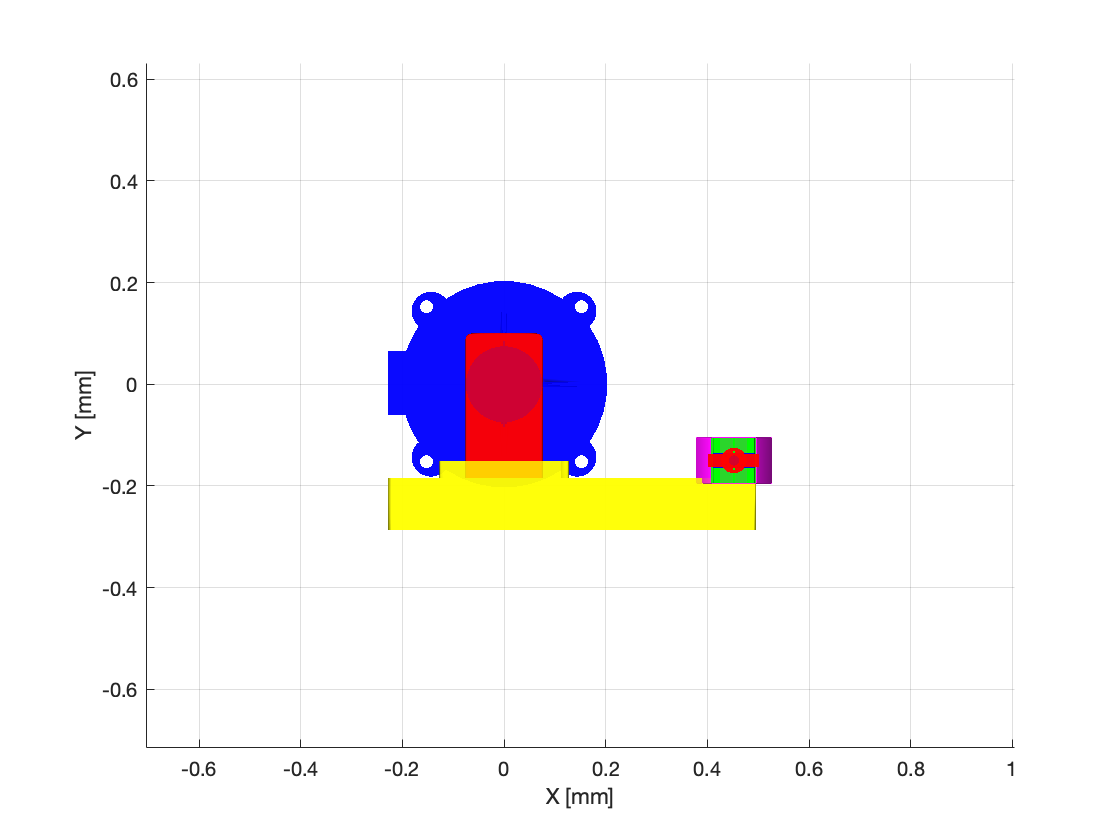

FVsPlot(L6.faces,V_6_0(1:3,:)',[1 0 0])

## Plot Function

Plot_Puma_Fib(qr)

## Animating

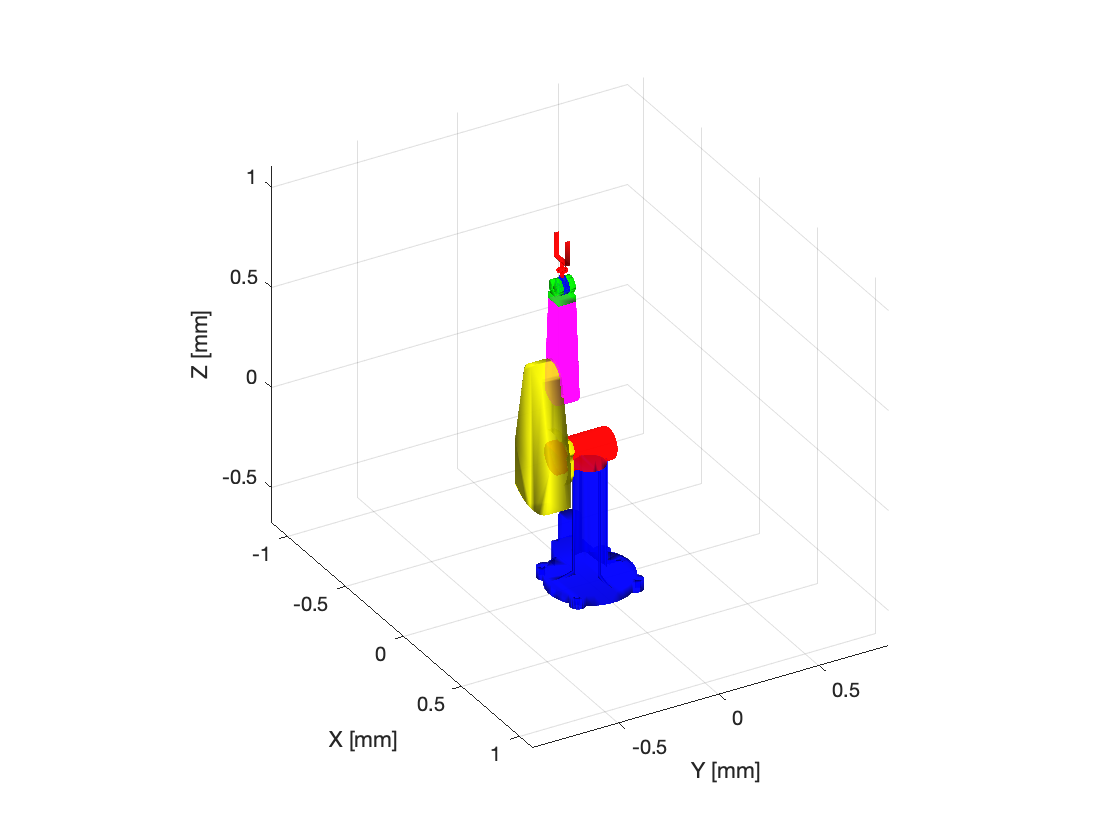

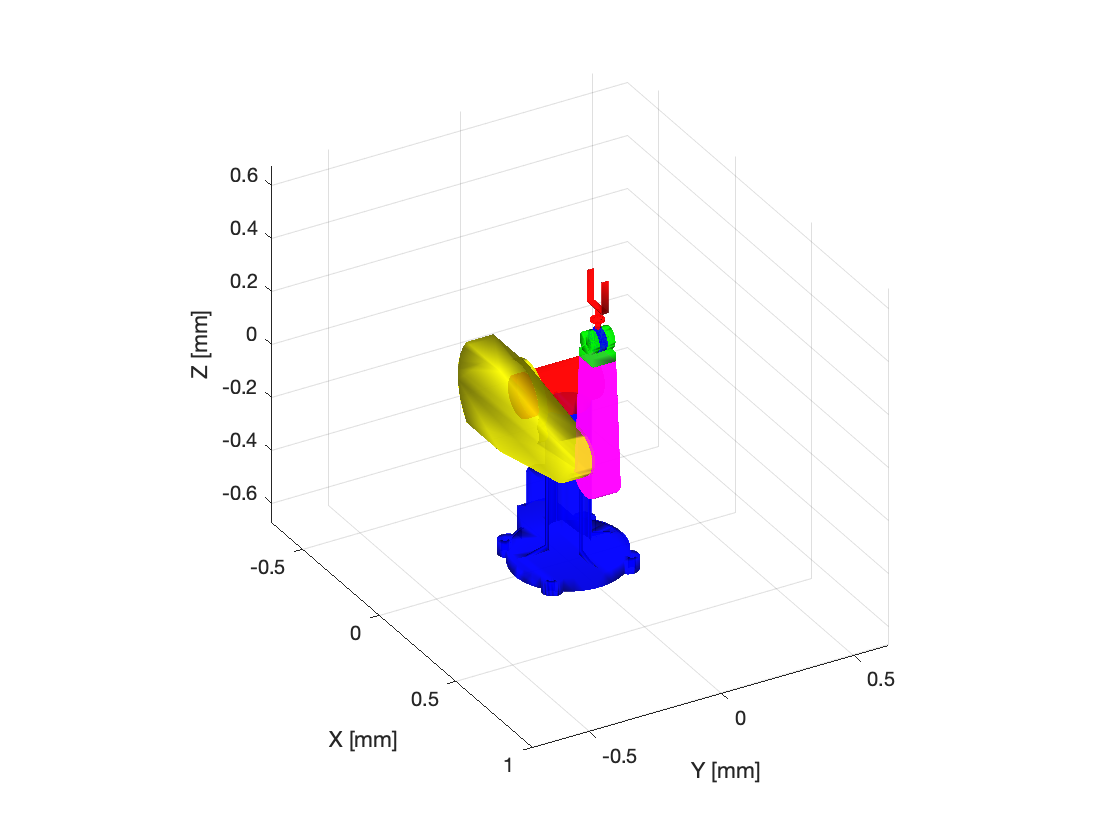

q1_a=linspace(0,pi,20)';
q2_a=linspace(0,pi/2,20)';
q3_a=linspace(0,-pi/2,20)';
q4_a=zeros(20,1);
q5_a=zeros(20,1);
q6_a=zeros(20,1);
qq= [q1_a q2_a q3_a q4_a q5_a q6_a];
figure
for i=1:20
    Plot_Puma_Fib(qq(i,:));
    drawnow
    clf
end

## Functions

function [L0 L1 L2 L3 L4 L5 L6]=Get_Link_V_F
    [V0,F0,N,name]=stlRead('link0.stl');
    L0.vertices = V0;
    L0.faces = F0;
    [V1,F1,N,name]=stlRead('link1.stl');
    L1.vertices = V1;
    L1.faces = F1;
    [V2,F2,N,name]=stlRead('link2.stl');
    L2.vertices = V2;
    L2.faces = F2;
    [V3,F3,N,name]=stlRead('link3.stl');
    L3.vertices = V3;
    L3.faces = F3;
    [V4,F4,N,name]=stlRead('link4.stl');
    L4.vertices = V4;
    L4.faces = F4;
    [V5,F5,N,name]=stlRead('link5.stl');
    L5.vertices = V5;
    L5.faces = F5;
    [V6,F6,N,name]=stlRead('link6.stl');
    L6.vertices =V6;
    L6.faces = F6;
end
%%%%%%%%

function T_b_a=link_A_B_Std(alpha,a,d,theta)
    T_b_a=trotz(theta)*transl(0,0,d)*transl(a,0,0)*trotx(alpha);
end
%%%%%%%%

function T_b_a=FVsPlot(F,V,color)
    patch(   'Faces',F, ...
             'Vertices',V, ...
             'FaceColor',color, ...
             'FaceAlpha',0.8,...
             'EdgeColor',       'none',        ...
             'FaceLighting',    'gouraud',     ...
             'AmbientStrength', 0.15);
    
    % Add a camera light, and tone down the specular highlighting
    camlight('headlight');
    material('dull');
    
    grid on
    xlabel 'X [mm]'
    ylabel 'Y [mm]'
    zlabel 'Z [mm]'
end

%%%%%%

function Plot_Puma_Fib(q)
    [L0 L1 L2 L3 L4 L5 L6]=Get_Link_V_F;
    
    % Transform compound
    T_1_0=link_A_B_Std(pi/2,0,0,q(1));
    T_2_1=link_A_B_Std(0,0.4318,0,q(2));
    T_3_2=link_A_B_Std(-pi/2,0.0203,0.15005,q(3));
    T_4_3=link_A_B_Std(pi/2,0,0.4318,q(4));
    T_5_4=link_A_B_Std(-pi/2,0,0,q(5));
    T_6_5=link_A_B_Std(0,0,0,q(6));
    
    % Operator
    V_1_0=T_1_0*                                [L1.vertices';ones(1,length(L1.vertices))];
    V_2_0=T_1_0*T_2_1*                          [L2.vertices';ones(1,length(L2.vertices))];
    V_3_0=T_1_0*T_2_1*T_3_2*                    [L3.vertices';ones(1,length(L3.vertices))];
    V_4_0=T_1_0*T_2_1*T_3_2*T_4_3*              [L4.vertices';ones(1,length(L4.vertices))];
    V_5_0=T_1_0*T_2_1*T_3_2*T_4_3*T_5_4*        [L5.vertices';ones(1,length(L5.vertices))];
    V_6_0=T_1_0*T_2_1*T_3_2*T_4_3*T_5_4*T_6_5*  [L6.vertices';ones(1,length(L6.vertices))];
    
    % Plotting
    clf
    axis equal
    view (60,30)
    FVsPlot(L0.faces,L0.vertices,[0 0 1]);
    FVsPlot(L1.faces,V_1_0(1:3,:)',[1 0 0]);
    FVsPlot(L2.faces,V_2_0(1:3,:)',[1 1 0]);
    FVsPlot(L3.faces,V_3_0(1:3,:)',[1 0 1]);
    FVsPlot(L4.faces,V_4_0(1:3,:)',[0 1 0]);
    FVsPlot(L5.faces,V_5_0(1:3,:)',[0 0 1]);
    FVsPlot(L6.faces,V_6_0(1:3,:)',[1 0 0]);
end